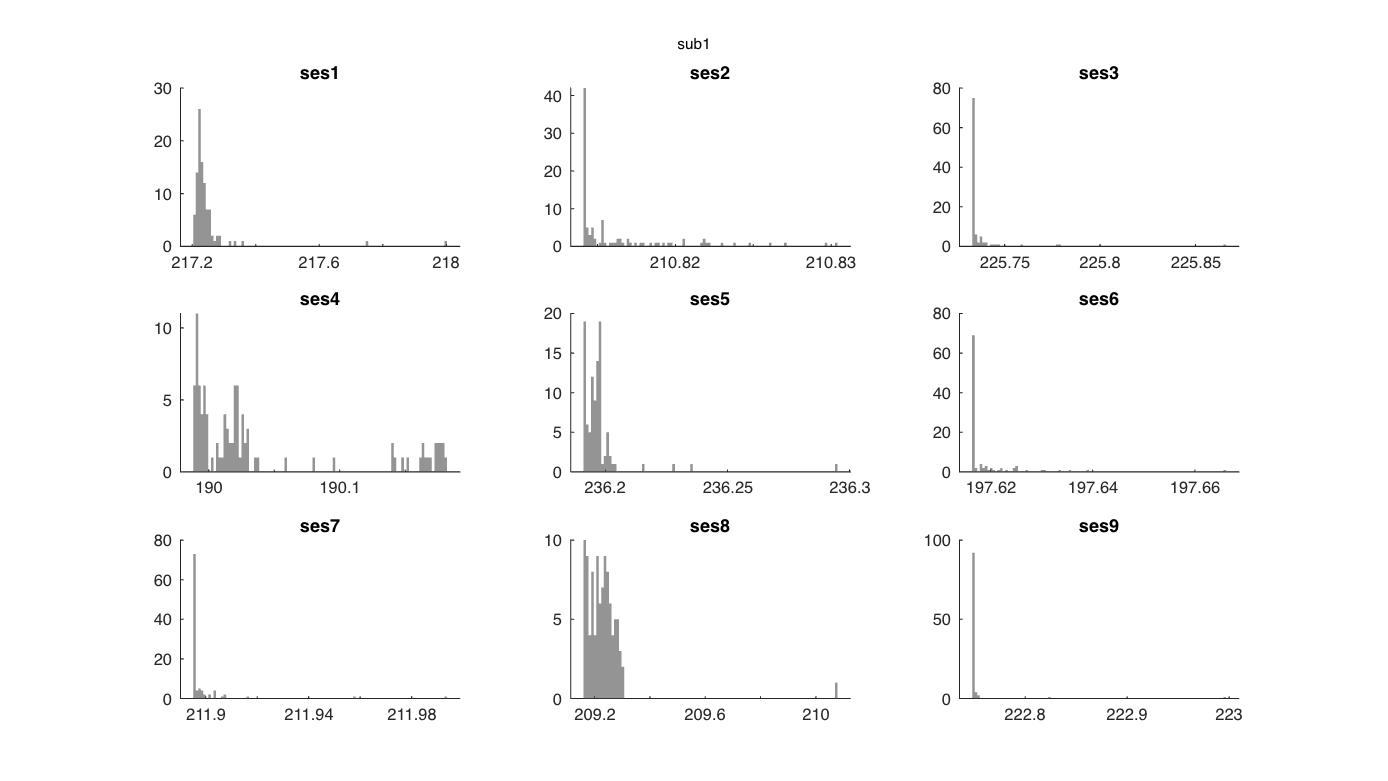

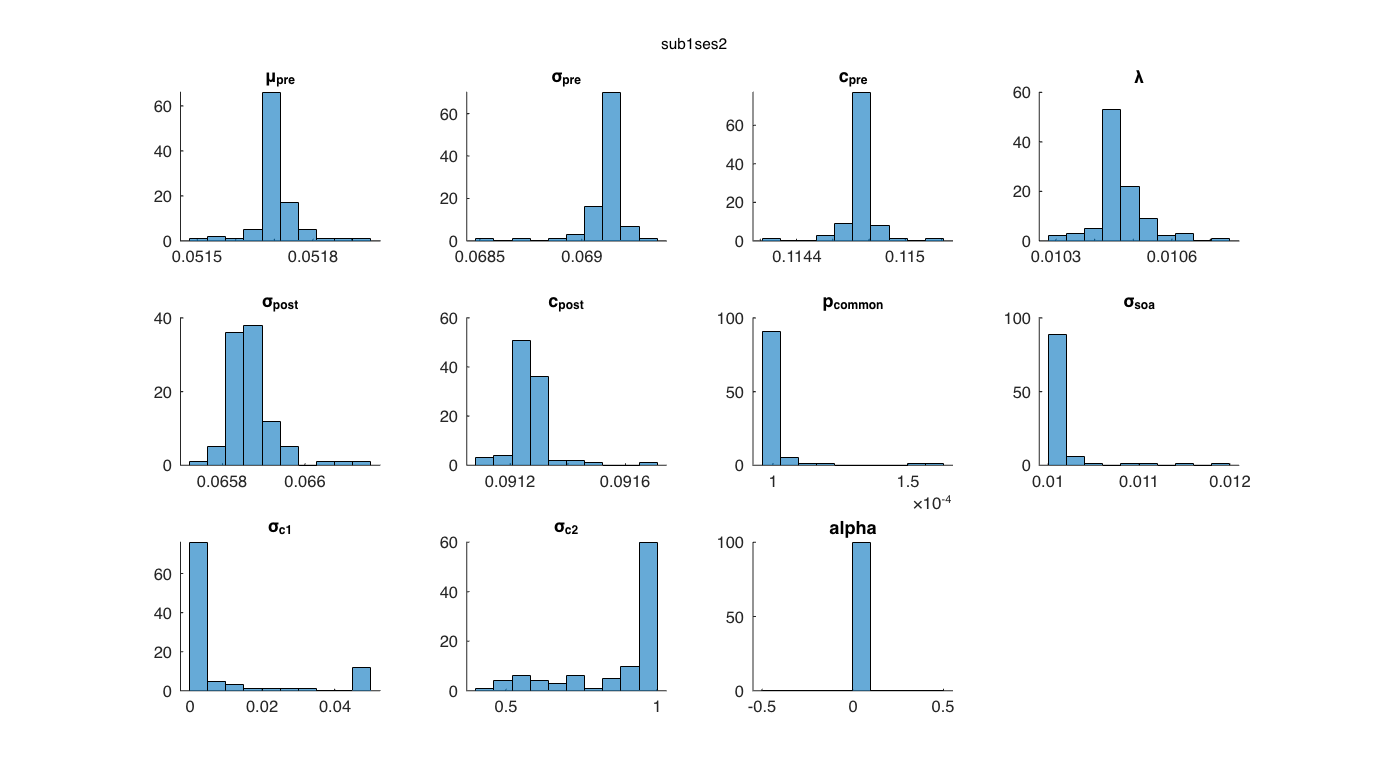

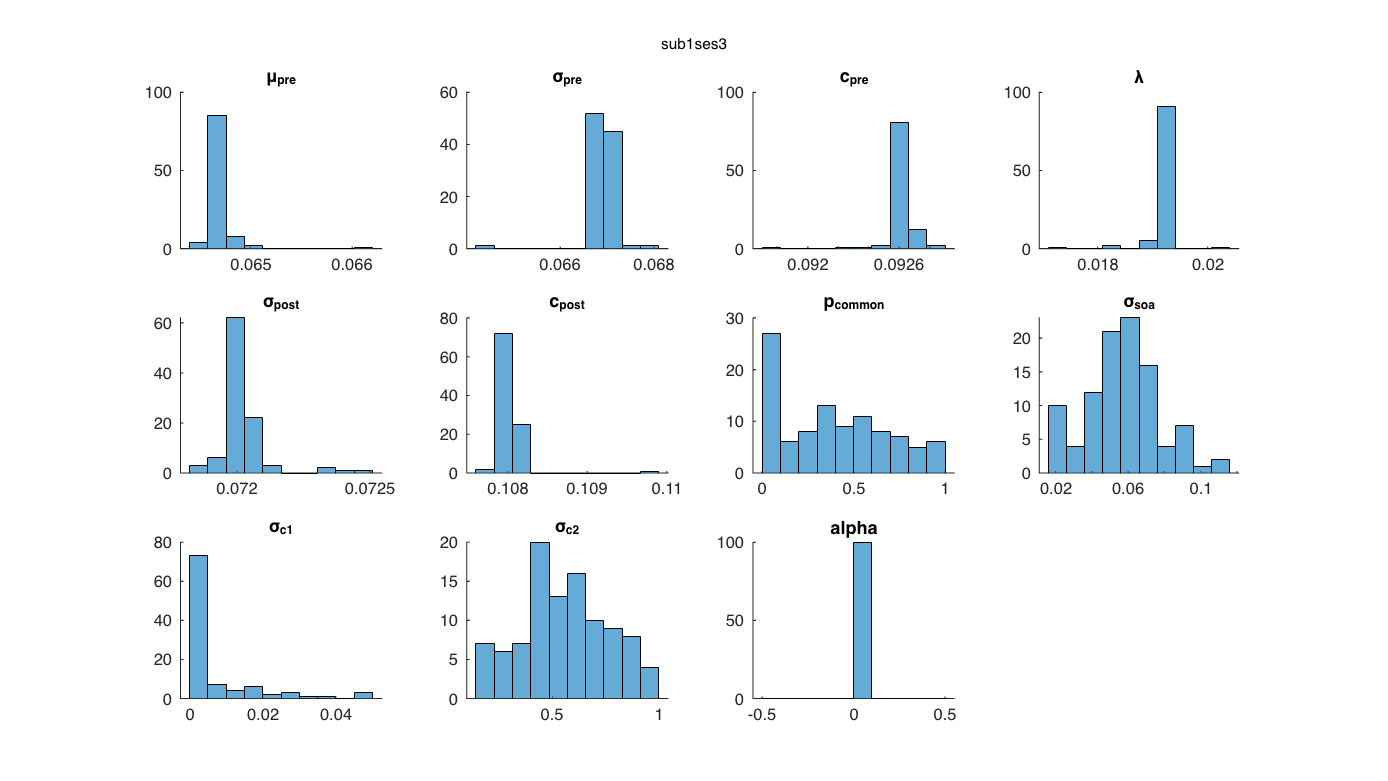

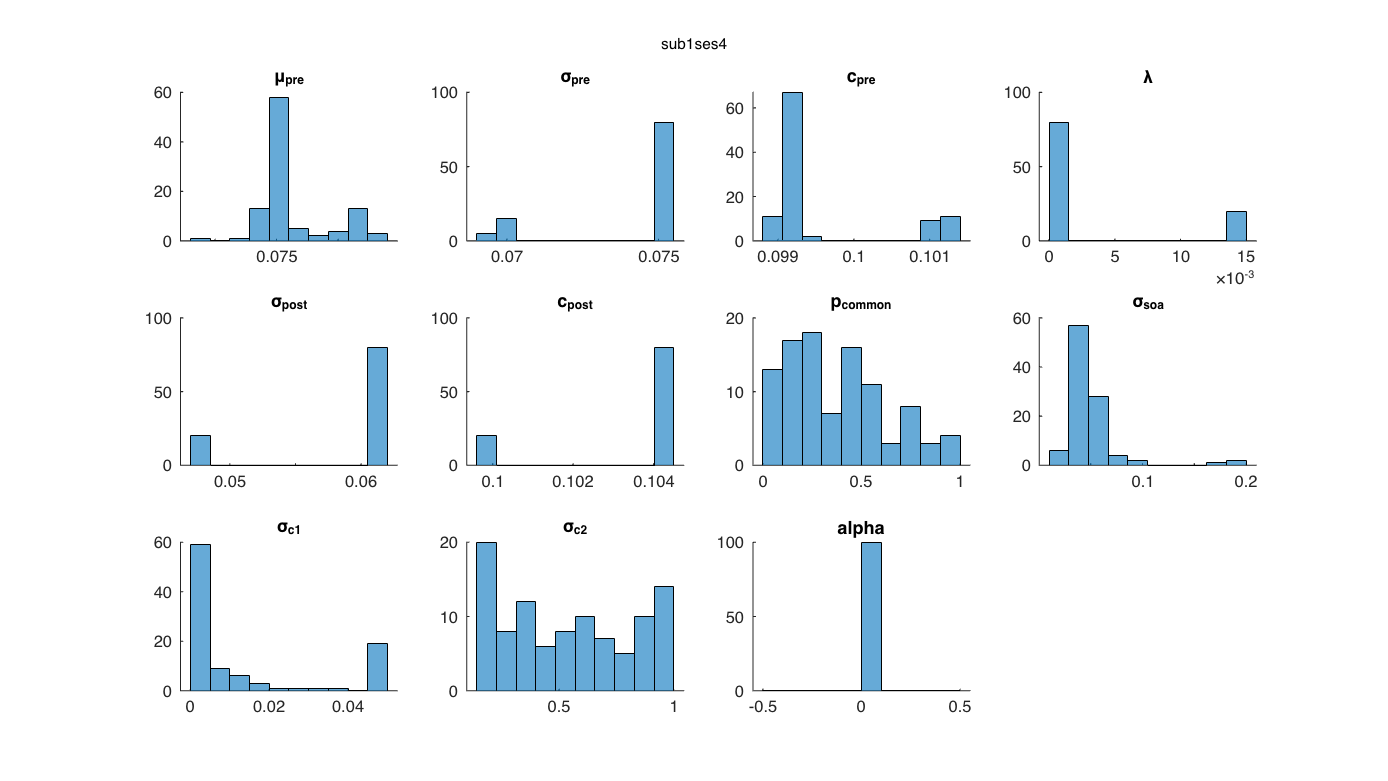

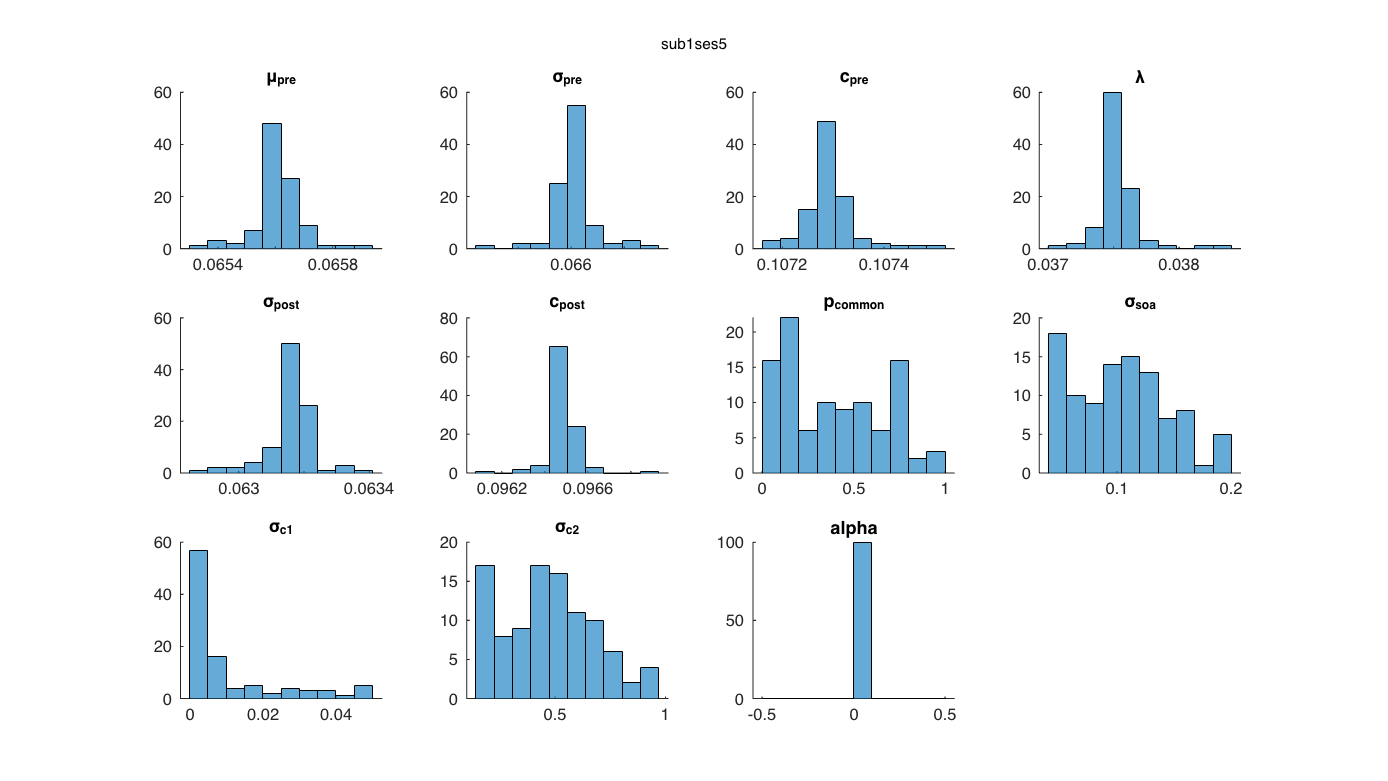

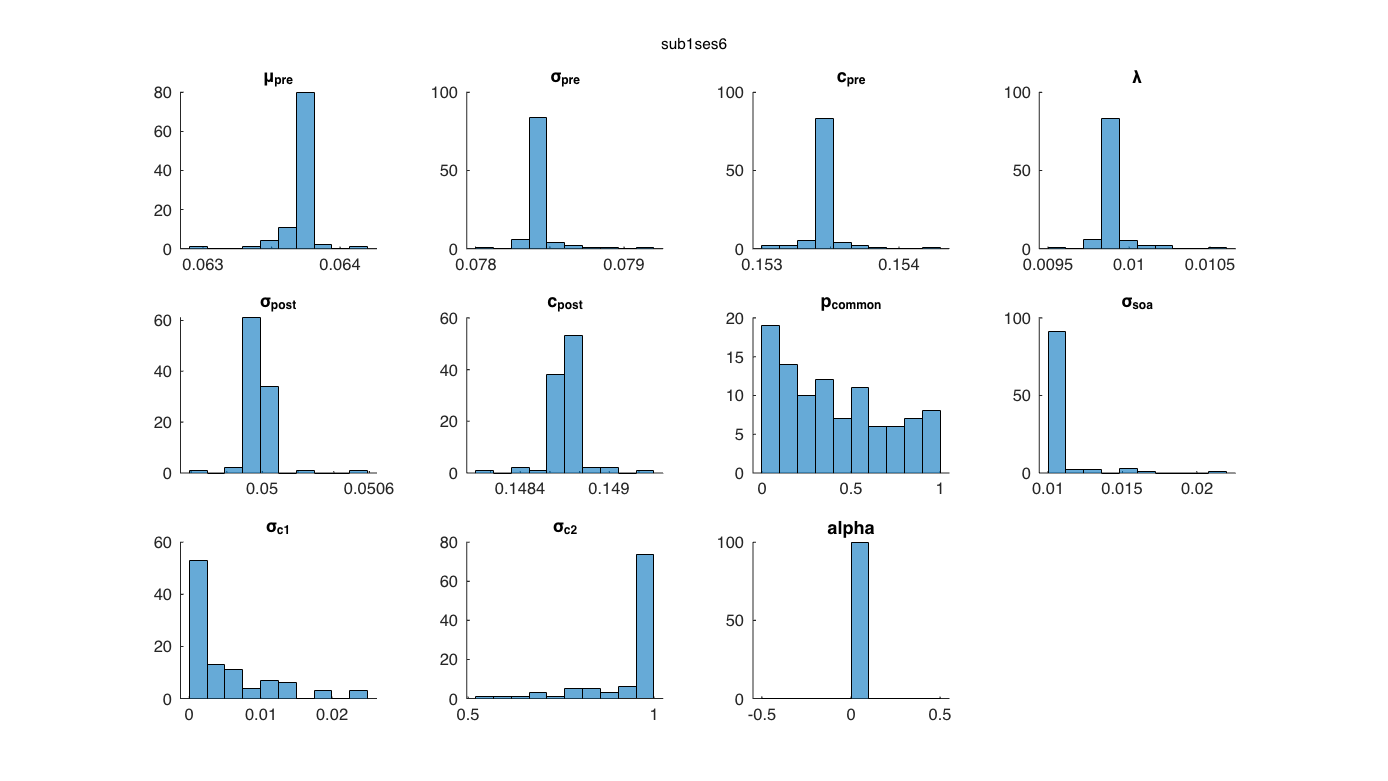

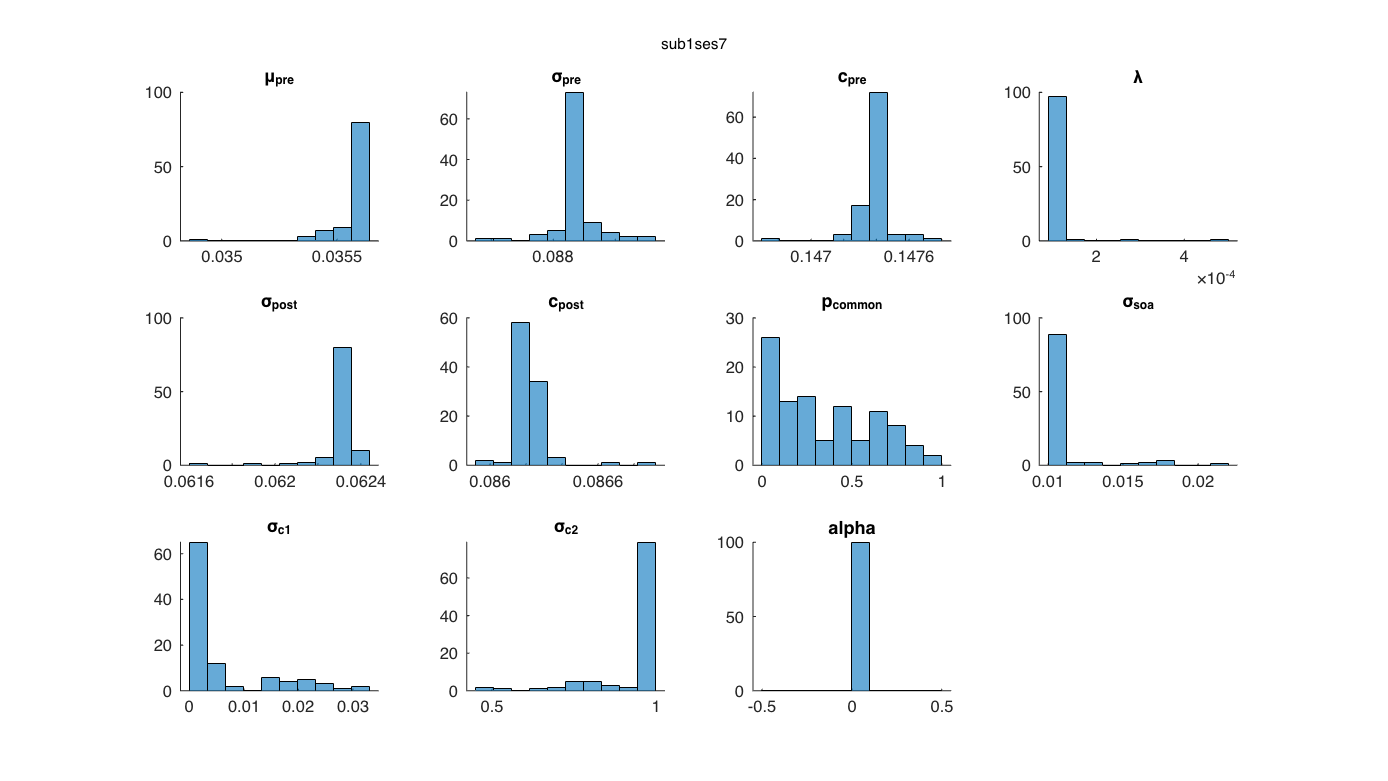

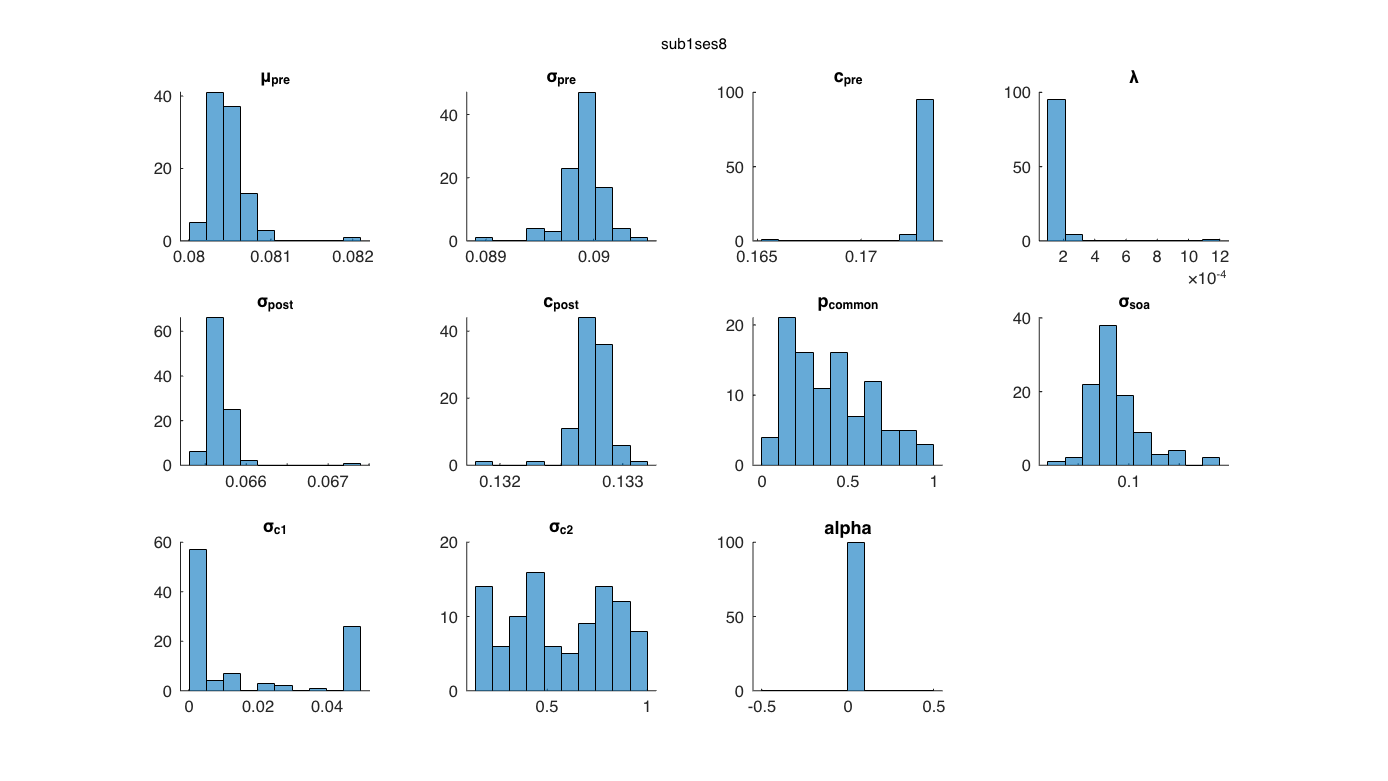

% This script takes the fitting results from a1_modelFitting.m and plots
% the distribution of fitted parameters (as we fitted 100 times for each
% session, each subject)


clear all; clc;

load("a1_modelFittingResults_v6.mat")

all_sub = 1;
all_ses = 1:9;

for sub = all_sub

    f1 =  figure; set(gcf, 'Position', get(0, 'Screensize'));
    sgtitle(['sub' num2str(sub)])
    
    for  ses = all_ses

        % plot nLL on the same figure
        figure(f1);
        subplot(3,3,ses); hold on
        set(gca, 'LineWidth', 1, 'FontSize', 15)
        h = histogram(model(sub, ses).minNLL, 100);
        h.FaceColor = repmat(0.3, 1, 3); h.EdgeColor = 'none';
        title(['ses' num2str(ses)])

        % plot parameter distribution
        f2 = figure; hold on; set(gcf, 'Position', get(0, 'Screensize'));
        sgtitle(['sub' num2str(sub) 'ses' num2str(ses)])

        for i = 1:model(sub, ses).numPara
            figure(f2); subplot(3,4,i); hold on;
            set(gca, 'LineWidth', 1, 'FontSize', 15)
            histogram(model(sub, ses).estimatedP(:,i), 10)
            title(model(sub, ses).paraID{i})
        end

    end

end